% syms r t psi t_0 v_x v_y
% 
% aa=R_mat(psi-r*t_0)*(A_mat(r*t)-A_mat(r*t_0))*[v_x;v_y]
% 
% simplify(aa)



## Polynomial curve fitting

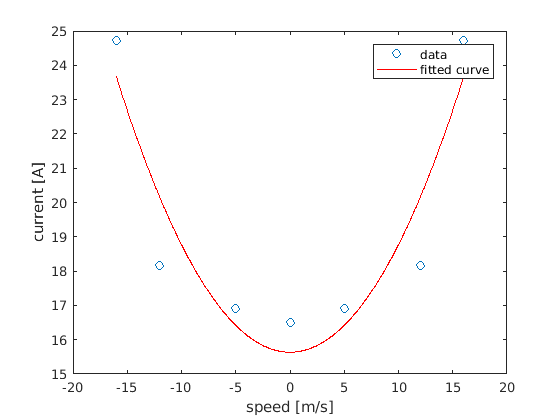

speed=[-16,-12,-5,0,5,12,16];
current=[24.73,18.17,16.9,16.5,16.9, 18.17, 24.73];

[pop2, gof]=fit(speed', current', 'poly2');
plot(pop2, speed, current ,'o')
xlabel('speed [m/s]');
ylabel('current [A]');


## Quadratic function generator

syms ss se sh N;

A=[1,1,1,ss;N^2,N,1,se;N^2,2*N,4,4*sh];
B=rref(A);

a=B(1,4);
b=B(2,4);
c=B(3,4);


## Test the quadFunc

ss=0;
se=1;
N=30;
i=1:N;
for j=i
    Qq(j)=quadFunc(ss,se,N,j);
    Ql(j)=linearFunc(ss,se,N,j);
    Qe(j)=expFunc(.3,N,j);
end

plot(i,[Qq;Ql;Qe])


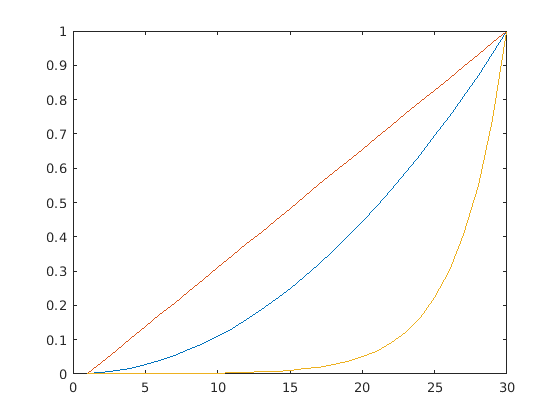

function A = A_mat(x)
    A=[sin(x), cos(x);-cos(x), sin(x)];

end

$$ans = u_{l}\,\left(r_{11}\,\bar{u_{l}}+r_{21}\,\bar{u_{u}}\right)+u_{u}\,\left(r_{12}\,\bar{u_{l}}+r_{22}\,\bar{u_{u}}\right)$$


function R = R_mat(x)
    R=[cos(x), -sin(x);sin(x), cos(x)];
end

function p_n = dfsdf (t,t_0, psi_0,r,v_b,p_n_0)
    p_n = p_n_0 + R(psi_0-r*t_0)*(A(r*t)-A(r*t_0))*v_b;
end

% function y = quadFunc(ss,sh,se,N,i)
%     a=(2*(2*sh - 2*se + N*se - 2*N*sh + N*ss))/(N*(N - 1)*(N - 2));
%     b=(4*sh - 4*se + N^2*se - 4*N^2*sh + 3*N^2*ss)/((N - 2)*(- N^2 + N));
%     c=(4*sh - 2*se + N*se - 4*N*sh + N^2*ss)/((N - 1)*(N - 2));
%     
%     y=a*i^2+b*i+c;
% end

function y = quadFunc(ss,se,N,i)
    b=0;
    c=(se-ss*N^2)/(1-N^2);
    a=ss-c;
    
    y=a*i^2+b*i+c;
end

function y = linearFunc(ss,se,N,i)
    y=(((se-ss)/(N-1))*(i-1)+ss);
end

function y = expFunc(a,N,i)
    y=(exp(a*i)-exp(a))/(exp(a*N)-exp(a));
end